close all
clear clear

body1 = rigidBody('body1')

body1 =   rigidBody with properties:

            Name: 'body1'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


jnt1 = rigidBodyJoint('jnt1', 'revolute')

jnt1 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt1'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


jnt1.PositionLimits = [-3.05433, 3.05433];
tform = trvec2tform([0,0,0])

tform =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


setFixedTransform(jnt1,tform)
body1.Joint = jnt1

body1 =   rigidBody with properties:

            Name: 'body1'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


robot = rigidBodyTree;
addBody(robot, body1,'base')



body2 = rigidBody('body2')

body2 =   rigidBody with properties:

            Name: 'body2'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


jnt2 = rigidBodyJoint('jnt2', 'revolute')

jnt2 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt2'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


tform2 = trvec2tform([0, 0, 0.193])*eul2tform([0, 0, pi/2]); 
jnt2.PositionLimits = [-1.5708,0.6405358];
setFixedTransform(jnt2,tform2);
body2.Joint = jnt2;
addBody(robot,body2,'body1');


body3 = rigidBody('body3')

body3 =   rigidBody with properties:

            Name: 'body3'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


jnt3 = rigidBodyJoint('jnt3', 'revolute')

jnt3 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt3'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


tform3 = trvec2tform([0, 0.21, 0]);
jnt3.PositionLimits = [-1.39626,1.5708];
setFixedTransform(jnt3,tform3);
body3.Joint = jnt3;
addBody(robot,body3,'body2');


body4 = rigidBody('body4')

body4 =   rigidBody with properties:

            Name: 'body4'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


jnt4 = rigidBodyJoint('jnt4', 'revolute')

jnt4 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt4'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


tform4 = trvec2tform([0.0415, 0.03, 0])*eul2tform([0, pi/2, 0]);
jnt4.PositionLimits = [-3.05433, 3.05433];
setFixedTransform(jnt4,tform4);
body4.Joint = jnt4;
addBody(robot,body4,'body3');

body5 = rigidBody('body5')

body5 =   rigidBody with properties:

            Name: 'body5'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


jnt5 = rigidBodyJoint('jnt5', 'revolute')

jnt5 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt5'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


tform5 = trvec2tform([0, 0, 0.180])*eul2tform([0, -pi/2, 0]);
jnt5.PositionLimits = [-1.74533,1.91986];
setFixedTransform(jnt5,tform5);
body5.Joint = jnt5;
addBody(robot,body5,'body4');

body6 = rigidBody('body6')

body6 =   rigidBody with properties:

            Name: 'body6'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


jnt6 = rigidBodyJoint('jnt6', 'revolute')

jnt6 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt6'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


tform6 = trvec2tform([0.0237, 0, 0])*eul2tform([0, pi/2, 0]);
jnt6.PositionLimits = [-2.5743606, 2.5743606];
setFixedTransform(jnt6,tform6);
body6.Joint = jnt6;
addBody(robot,body6,'body5');

body7 = rigidBody('body7')

body7 =   rigidBody with properties:

            Name: 'body7'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


jnt7 = rigidBodyJoint('jnt7', 'fixed')

jnt7 =   rigidBodyJoint with properties:

                      Type: 'fixed'
                      Name: 'jnt7'
                 JointAxis: [NaN NaN NaN]
            PositionLimits: [0 0]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


tform7 = trvec2tform([0, 0, 0.08])*eul2tform([0, 0, 0]);
setFixedTransform(jnt7,tform7);
body7.Joint = jnt7;
addBody(robot,body7,'body6');

show(robot)

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


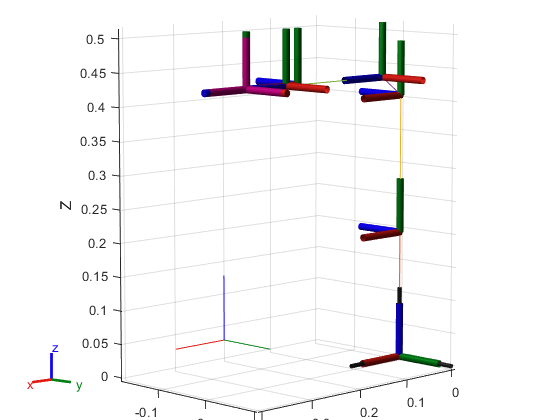

axis tight

% pos = [0.30 0 0.3];
% pos = [0.15 0.15 0.025];
% pos = [0.2 0.18 0.1];
% pos = [0.2 0.18 0.0001];
% pos = [0.25 0.16 0.1];
% pos = [0.25 0.16 0.0001];
% pos = [0.2 -0.18 0.1];
% pos = [0.2 -0.18 0.008];
% pos = [0.2 -0.18 (0.008+0.01)];
pos = [0.2 -0.18 (0.008+0.01+0.01)];

ros = [1.5*pi,pi,0];
poseTF = trvec2tform(pos)*eul2tform(ros);

hold on
plotTransforms(pos,eul2quat([0 0 0]),FrameSize=0.1);


ik = inverseKinematics("RigidBodyTree",robot)

ik =   inverseKinematics with properties:

       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]


weights = [0.9 0.9 0.9 1 1 1];
initialguess = homeConfiguration(robot)

initialguess = 1×6 struct array with fields:
    JointName
    JointPosition


[configSoln,solnInfo] = ik("body7",poseTF,weights,initialguess)

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


solnInfo = struct with fields:
           Iterations: 30
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7639e-09
             ExitFlag: 1
               Status: 'success'


figure
show(robot,configSoln,PreservePlot=false)

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


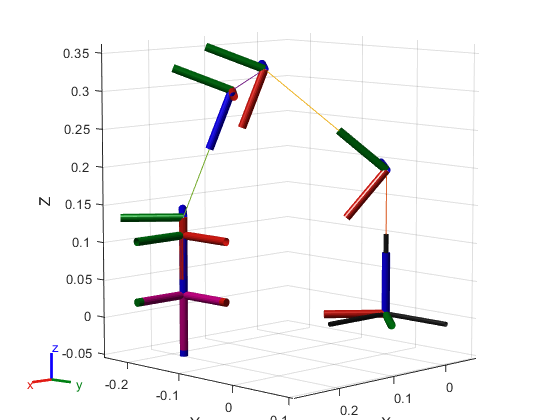

axis tight

jointPositions = [configSoln.JointPosition]'

jointPositions =    -0.7328
   -0.8756
   -0.3265
    0.0000
   -0.3687
   -0.7328


jointPositionText = strjoin(string([configSoln.JointPosition]), ',')

jointPositionText = "-0.73282,-0.87563,-0.32652,1.2597e-08,-0.36865,-0.73282"

jointPositionText

jointPositionText = "-0.73282,-0.87563,-0.32652,1.2597e-08,-0.36865,-0.73282"